# PHYS 361: Loops

## for loops 

Sometimes you want to repeat a set of operations over and over again. The next few lines of code give an example.

format short

for k=10:-.1:1
    k
end

k = 10

k = 9.9000

k = 9.8000

k = 9.7000

k = 9.6000

k = 9.5000

k = 9.4000

k = 9.3000

k = 9.2000

k = 9.1000

k = 9

k = 8.9000

k = 8.8000

k = 8.7000

k = 8.6000

k = 8.5000

k = 8.4000

k = 8.3000

k = 8.2000

k = 8.1000

k = 8

k = 7.9000

k = 7.8000

k = 7.7000

k = 7.6000

k = 7.5000

k = 7.4000

k = 7.3000

k = 7.2000

k = 7.1000

k = 7

k = 6.9000

k = 6.8000

k = 6.7000

k = 6.6000

k = 6.5000

k = 6.4000

k = 6.3000

k = 6.2000

k = 6.1000

k = 6

k = 5.9000

k = 5.8000

k = 5.7000

k = 5.6000

k = 5.5000

k = 5.4000

k = 5.3000

k = 5.2000

k = 5.1000

k = 5

k = 4.9000

k = 4.8000

k = 4.7000

k = 4.6000

k = 4.5000

k = 4.4000

k = 4.3000

k = 4.2000

k = 4.1000

k = 4

k = 3.9000

k = 3.8000

k = 3.7000

k = 3.6000

k = 3.5000

k = 3.4000

k = 3.3000

k = 3.2000

k = 3.1000

k = 3

k = 2.9000

k = 2.8000

k = 2.7000

k = 2.6000

k = 2.5000

k = 2.4000

k = 2.3000

k = 2.2000

k = 2.1000

k = 2

k = 1.9000

k = 1.8000

k = 1.7000

k = 1.6000

k = 1.5000

k = 1.4000

k = 1.3000

k = 1.2000

k = 1.1000

k = 1

That is a pretty boring loop, but note what it is doing. Every time it runs through the loop, the variable k is replaced with a new value defined by the array 1:10. The for and end (which are blue because they are keywords) tell MATLAB where the looped code begins and ends. Here is another example,

format short

for angle=0:pi/2:2*pi
    anscos=cos(angle) 
    anssin=sin(angle)
end

anscos = 1

anssin = 0

anscos = 6.1232e-17

anssin = 1

anscos = -1

anssin = 1.2246e-16

anscos = -1.8370e-16

anssin = -1

anscos = 1

anssin = -2.4493e-16

In the example below, I am summing the first 20 terms of the Taylor series for $sin(35^{\circ})$.


$$sin(x)=\sum_{k=0}^{\infty}\frac{(-1)^kx^{2k+1}}{(2k+1)!}$$


clear;              %I'm reusing variable names so clear to be safe

format long;

n=20;               %Specify number of terms

xrad=35.*pi/180;    %Convert degrees to rad

sin(xrad)           %Get real value for comparison

ans =    0.573576436351046



S=0;    %Since I am summing by adding values to S, I have to specify an initial value
for k=0:n-1
    k
    (-1)^k*xrad^(2*k+1)/factorial(2*k+1)
    S=S+(-1)^k*xrad^(2*k+1)/factorial(2*k+1)    %Could have used the shorthand S=+ for S=X+
end

k =      0


ans =    0.610865238198015


S =    0.610865238198015


k =      1


ans =   -0.037991372675693


S =    0.572873865522322


k =      2


ans =      7.088360775157756e-04


S =    0.573582701599838


k =      3


ans =     -6.297777995383784e-06


S =    0.573576403821842


k =      4


ans =      3.263966364021618e-08


S =    0.573576436461506


k =      5


ans =     -1.107245217996923e-10


S =    0.573576436350782


k =      6


ans =      2.648561360175052e-13


S =    0.573576436351046


k =      7


ans =     -4.706321244819248e-16


S =    0.573576436351046


k =      8


ans =      6.456594143375576e-19


S =    0.573576436351046


k =      9


ans =     -7.044792498515135e-22


S =    0.573576436351046


k =     10


ans =      6.259068998672118e-25


S =    0.573576436351046


k =     11


ans =     -4.615832558472402e-28


S =    0.573576436351046


k =     12


ans =      2.870711966764079e-31


S =    0.573576436351046


k =     13


ans =     -1.525960638926587e-34


S =    0.573576436351046


k =     14


ans =      7.012584801037195e-38


S =    0.573576436351046


k =     15


ans =     -2.813753196727003e-41


S =    0.573576436351046


k =     16


ans =      9.942896234961068e-45


S =    0.573576436351046


k =     17


ans =     -3.117861143250844e-48


S =    0.573576436351046


k =     18


ans =      8.734606985511480e-52


S =    0.573576436351046


k =     19


ans =     -2.199307670312009e-55


S =    0.573576436351046


Note that after the first few terms, you can't tell that the sum is still an approximate value. That is because MATLAB does not show you very many digits by default. To see more, you can specify the format. The default format is short, which shows you four decimal digits or values in scientific notation. The long format will show you 15 digits. 

clear;
doc format     %You should take a look at the documentation
format long    %Tell MATLAB you want to print variables in the long format

S=0;
n=20;

xrad=35.*pi/180;
sin(xrad)

ans =    0.573576436351046



for k=0:n-1
    S=S+(-1)^k*xrad^(2*k+1)/factorial(2*k+1);
end

## **While loops**

Sometimes you don't know how many times you want to loop through a few lines of code. You might want to loop until a condition in your code is true or false. For example, run the following code

clear all;

n=1;

while n~=10
    n=n+1
   
end

n =      2


n =      3


n =      4


n =      5


n =      6


n =      7


n =      8


n =      9


n =     10


Notice that the loop stopped when the condition became false because n was equal to 10. These types of loops are useful but also dangerous. They are dangerous because if you make a mistake, your condition might never be true, and your loop will continue indefinitely. So be careful! 

## Hault running code and a protective measure for infinite loops

If your code enters an infinite loop (or a while loop that runs indefinitely) because the exit condition is never met, you can (sometimes) stop MATLAB from running by typing cntrl-c or cntrl-z. In the script editor, you can also (sometimes) hit the "Pause" button under the editor tab and then "Stop." I say "sometimes," because sometimes you need something more powerful like force quitting MATLAB.

Here is another way to safeguard your code from infinite loops:

clear all;

n=1;
s=1;

while s >= 1 & n < 100
    s = s*2   %Intended code or the calculation you want to make
    
    n=n+1    %Counter to prevent the loop from running more than 100 times
end

s =      2


n =      2


s =      4


n =      3


s =      8


n =      4


s =     16


n =      5


s =     32


n =      6


s =     64


n =      7


s =    128


n =      8


s =    256


n =      9


s =    512


n =     10


s =         1024


n =     11


s =         2048


n =     12


s =         4096


n =     13


s =         8192


n =     14


s =        16384


n =     15


s =        32768


n =     16


s =        65536


n =     17


s =       131072


n =     18


s =       262144


n =     19


s =       524288


n =     20


s =      1048576


n =     21


s =      2097152


n =     22


s =      4194304


n =     23


s =      8388608


n =     24


s =     16777216


n =     25


s =     33554432


n =     26


s =     67108864


n =     27


s =    134217728


n =     28


s =    268435456


n =     29


s =    536870912


n =     30


s =      1.073741824000000e+09


n =     31


s =      2.147483648000000e+09


n =     32


s =      4.294967296000000e+09


n =     33


s =      8.589934592000000e+09


n =     34


s =      1.717986918400000e+10


n =     35


s =      3.435973836800000e+10


n =     36


s =      6.871947673600000e+10


n =     37


s =      1.374389534720000e+11


n =     38


s =      2.748779069440000e+11


n =     39


s =      5.497558138880000e+11


n =     40


s =      1.099511627776000e+12


n =     41


s =      2.199023255552000e+12


n =     42


s =      4.398046511104000e+12


n =     43


s =      8.796093022208000e+12


n =     44


s =      1.759218604441600e+13


n =     45


s =      3.518437208883200e+13


n =     46


s =      7.036874417766400e+13


n =     47


s =      1.407374883553280e+14


n =     48


s =      2.814749767106560e+14


n =     49


s =      5.629499534213120e+14


n =     50


s =      1.125899906842624e+15


n =     51


s =      2.251799813685248e+15


n =     52


s =      4.503599627370496e+15


n =     53


s =      9.007199254740992e+15


n =     54


s =      1.801439850948198e+16


n =     55


s =      3.602879701896397e+16


n =     56


s =      7.205759403792794e+16


n =     57


s =      1.441151880758559e+17


n =     58


s =      2.882303761517117e+17


n =     59


s =      5.764607523034235e+17


n =     60


s =      1.152921504606847e+18


n =     61


s =      2.305843009213694e+18


n =     62


s =      4.611686018427388e+18


n =     63


s =      9.223372036854776e+18


n =     64


s =      1.844674407370955e+19


n =     65


s =      3.689348814741910e+19


n =     66


s =      7.378697629483821e+19


n =     67


s =      1.475739525896764e+20


n =     68


s =      2.951479051793528e+20


n =     69


s =      5.902958103587057e+20


n =     70


s =      1.180591620717411e+21


n =     71


s =      2.361183241434823e+21


n =     72


s =      4.722366482869645e+21


n =     73


s =      9.444732965739290e+21


n =     74


s =      1.888946593147858e+22


n =     75


s =      3.777893186295716e+22


n =     76


s =      7.555786372591432e+22


n =     77


s =      1.511157274518286e+23


n =     78


s =      3.022314549036573e+23


n =     79


s =      6.044629098073146e+23


n =     80


s =      1.208925819614629e+24


n =     81


s =      2.417851639229258e+24


n =     82


s =      4.835703278458517e+24


n =     83


s =      9.671406556917033e+24


n =     84


s =      1.934281311383407e+25


n =     85


s =      3.868562622766813e+25


n =     86


s =      7.737125245533627e+25


n =     87


s =      1.547425049106725e+26


n =     88


s =      3.094850098213451e+26


n =     89


s =      6.189700196426901e+26


n =     90


s =      1.237940039285380e+27


n =     91


s =      2.475880078570761e+27


n =     92


s =      4.951760157141521e+27


n =     93


s =      9.903520314283042e+27


n =     94


s =      1.980704062856608e+28


n =     95


s =      3.961408125713217e+28


n =     96


s =      7.922816251426434e+28


n =     97


s =      1.584563250285287e+29


n =     98


s =      3.169126500570574e+29


n =     99


s =      6.338253001141147e+29


n =    100


The code would have run indefinitely, but I limited the number of times the loop can run to 100, which is a value that is  larger than the number of times I expect the non-broken loop to run.

## Break Statements

Break statements are another way to exit a for or while loop early. Previously, I showed you one way to safeguard a while loop from running indefinitely. Here is another:

n=1;
s=1;

while s >= 1 & (n<100000)
    s = s + 1;
    n=n+1;
    
    if n > 5000
        fprintf('Exiting loop, too many iterations')
        n
        break;
    end
end

Exiting loop, too many iterations

n =         5001


Here if the condition of the if statement is met, the break command tells MATLAB to exit the loop (go to the next end) and move on. If the break command is in a nested loop (which you will learn about next), the code will move out of the inner loop and into the surrounding outer loop.

**Note**: I put a message in there if the break condition is met. Putting statements like that in your code is a useful way to debug.

## The Continue Statement

The continue statement is similar to the break statement, but instead of exiting the loop the continue statment simply tells the code to move on to the next iteration of the loop without executing the code in the loop below the continue statement. This can be useful for skipping some calculations if a specific condition is met. For example, here the code outputs all the values except for 15 because it was told to skip to the next iteration of the loop in that case:

a = 9;
%while loop execution 
while a < 20
   a = a + 1; 
   if a == 15
      % skip the iteration 
      continue;
   end 
fprintf('value of a: %d\n', a);

end

value of a: 10
value of a: 11
value of a: 12
value of a: 13
value of a: 14
value of a: 16
value of a: 17
value of a: 18
value of a: 19
value of a: 20


## Nested Loops

Here is a simple example of a nested loop.

n=1;

for k=1:4
    for j=1:3
        for i=1:2
            fprintf('\n i=%i ,j=%i ,k=%i, n=%i',i,j,k,n)
            n=n+1;
        end
    end
end


 i=1 ,j=1 ,k=1, n=1
 i=2 ,j=1 ,k=1, n=2
 i=1 ,j=2 ,k=1, n=3
 i=2 ,j=2 ,k=1, n=4
 i=1 ,j=3 ,k=1, n=5
 i=2 ,j=3 ,k=1, n=6
 i=1 ,j=1 ,k=2, n=7
 i=2 ,j=1 ,k=2, n=8
 i=1 ,j=2 ,k=2, n=9
 i=2 ,j=2 ,k=2, n=10
 i=1 ,j=3 ,k=2, n=11
 i=2 ,j=3 ,k=2, n=12
 i=1 ,j=1 ,k=3, n=13
 i=2 ,j=1 ,k=3, n=14
 i=1 ,j=2 ,k=3, n=15
 i=2 ,j=2 ,k=3, n=16
 i=1 ,j=3 ,k=3, n=17
 i=2 ,j=3 ,k=3, n=18
 i=1 ,j=1 ,k=4, n=19
 i=2 ,j=1 ,k=4, n=20
 i=1 ,j=2 ,k=4, n=21
 i=2 ,j=2 ,k=4, n=22
 i=1 ,j=3 ,k=4, n=23
 i=2 ,j=3 ,k=4, n=24

Nested loops are often required to perform calculations on multidimensional data. For example, lets say I wanted to calculate the strength of the electric field from a positive charge placed at the origin in 3-dimensions cube. The magnitude of the field at a radial distance r is:


$$E=\frac{1}{4 \pi \epsilon_0}\frac{q\text{ }}{r^2 }$$


If I wanted to calculate the strength of the field in a  2 cm x 2 cm x 2 cm cube surrounding the charge I could code it up like this:

(**Note**: If you don't understand the code below, uncomment the fprinf to observe the output.  Notice how the nested loop iterates over the coordinates of a cube centered at the origin. Draw a picture and compare it.)

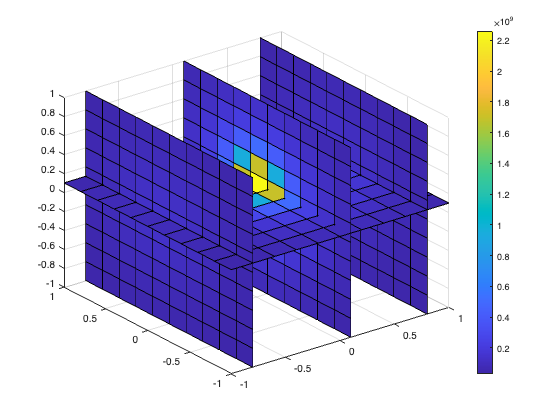

clear all;  %Clear my workspace so I start from scratch

epsilon=8.8e-12;  %Permitivity of free space (units C^2/N/m^2)
q=1e-6;           %Charge (units C)


%Define an empty array for the electric field, units (V/m or N/C)
E=zeros(11,11,11);


%loops over each element of the electric field matrix
for l=1:11
    for m=1:11
        for n=1:11
            
            %use the array indeces to find the x, y, z value 
            %assuming (0,0,0) is at the center of the cube, in meters
            x=(n-6)*.002;
            y=(m-6)*.002;
            z=(l-6)*.002;
            
            
            
            %Calculate the radial distance
            r=sqrt(x^2+y^2+z^2);
            
            %Find the electric field and store it in cube
            E(n,m,l)=1/(4*pi*epsilon)*q/r^2;
            
            %Uncomment out this line to observe the output
            %fprintf('E is %12.3f V/m at (x,y,z)=(%4.3f,%4.3f,%4.3f) m \n',E(n,m,l),x,y,z)
            
       
        end
    end
end

%Make a simple plot to illustrate that we have 
%build a cube of electric field values
[X,Y,Z] = meshgrid(-1:.2:1);


xslice = [-.8,.1,.8];   
yslice = [];
zslice = .1;
slice(X,Y,Z,E,xslice,yslice,zslice)
colorbar;